# Optimising for cost

The MATLAB Live Script "BoardCalculator.mlx" calculates the board length that is required to in order to cover the required shape for a specified board width.

This MATLAB Live Script will run over all the available board widths to acquire a length required for each width, then apply the cost per metre in order to calculate the optimal cost-versus-width.

## Defining the available boards and associated cost

In this section we define the board widths that are available along with their cost per metre.

boardWidths = [25; 32; 44; 57; 70; ...
                90; 95; 110; 121; 146; ...
                171; 197; 222];
            
costPerMetre = [4.79; 5.45; 7.33; 7.80; 9.58; ...
                11.38; 12.02; 13.65; 15.00; 18.05; ...
                23.26; 29.05; 32.75];

## Assemble project costs

In this section we will call the BoardCalculator in order to get the total length required for each board width.

   -1.4839

  213.8065

  Columns 1 through 22

   150   148   147   145   144   142   141   139   138   136   135   133   132   130   129   127   126   124   123   121   120   118

  Columns 23 through 44

   117   115   114   112   111   109   108   106   105   104   102   101    99    98    96    95    93    92    90    89    87    86

  Columns 45 through 63

    84    83    81    80    78    77    75    74    72    71    69    68    66    65    63    62    60    59    58

   150    43
   148    44
   147    45
   145    46
   144    47
   142    48
   141    49
   139    50
   138    51
   136    52
   135    53
   133    54
   132    55
   130    56
   129    57
   127    58
   126    59
   124    60
   123    61
   121    62
   120    63
   118    64
   117    65
   115    66
   114    67
   112    68
   111    69
   109    70
   108    71
   106    72
   105    73
   104    74
   102    75
   101    76
    99    77
    98    78
    96    79
    95    80
    93    81
    92    8

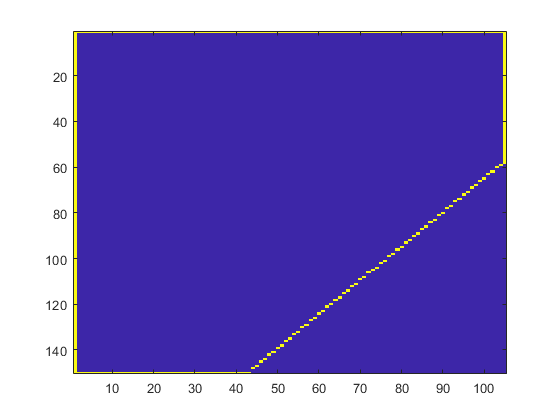

     0     0     0     0     0     0     0     0     0     0     0     0     7



Unrecognized function or variable 'reqdBoardLength'.

Error in boardLengthCalculator (line 93)
totalBoardLength = sum(reqdBoardLength);

reqdLengths = boardLengthCalculator(boardWidths);

totalCosts = reqdLengths .* costPerMetre;

plot(boardWidths, totalCosts)